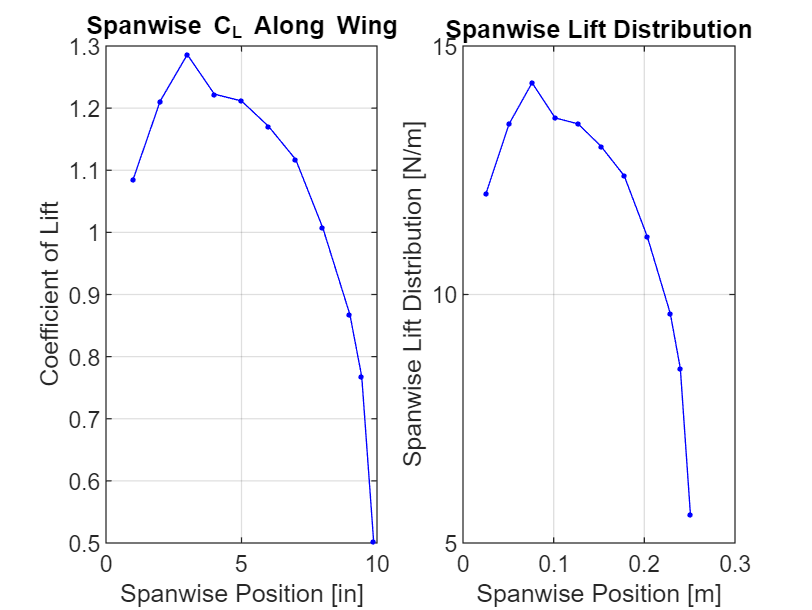

% House Cleaning 
clc
close all
clear vars

% Read in Port Locations
x = readmatrix('ClarkY14_PortLocations.xlsx');
x(10,:)= []; % Remove NaN row
spanwise_loc = [1;2;3;4;5;6;7;8;9;9.4375;9.875]; % Spanwise port locations
spanwise_meters = spanwise_loc * 0.0254; % Convert to meters
y_loc_inf = x(:,3); % Port Locations -- y-axis
z_loc_inf = x(:,4); % z-axis

% Add in 
y_loc_inf1 = [y_loc_inf(end);y_loc_inf(1:9);1;y_loc_inf(10:end)];
z_loc_inf1 = [z_loc_inf(end);z_loc_inf(1:9);0;z_loc_inf(10:end)];

chord_l = 3.5031; % Chord length of wing 
chord_l_m = 0.0254; % Chord length converted to meters
yc = y_loc_inf/chord_l; % Normalize the chord length


% c_p Function Call
[c_p_f,q_f] =calculate_c_p(yc,1,'FullSpanTest.csv');

% Preallocate 
C_L_f = zeros(1,length(spanwise_meters));
C_D_f = zeros(1,length(spanwise_meters));
w_0 = zeros(1,length(spanwise_meters));

% For Loop to Calculate C_l and C_d for Every Spanwise Position
for i = 1:length(spanwise_loc)
    [C_L_f(i),C_D_f(i),w_0(i)] = calculateC_l_d(q_f,y_loc_inf1,z_loc_inf1,yc,chord_l_m,chord_l,spanwise_loc(i),'FullSpanTest.csv');

end

% Plot Data

% C_L vs Distance
figure(1);
subplot(1,2,1)
plot(spanwise_loc,C_L_f,'.-b')
xlabel('Spanwise Position [in]')
grid on
ylabel('Coefficient of Lift')
title('Spanwise C_L Along Wing')

% w(x) vs Distance
subplot(1,2,2)
plot(spanwise_meters,w_0,'.-b')
xlabel('Spanwise Position [m]')
ylabel('Spanwise Lift Distribution [N/m]')
title('Spanwise Lift Distribution')
grid on

function [c_p,q_ave] = calculate_c_p(l,spanwise,filename)

f_data = load(filename);
logical_spanwise = f_data(:,9) == spanwise; % Uses data corresponding to aoa
f_data_spanwise = f_data(logical_spanwise,:);
rho_f = f_data_spanwise(:,3); % Free-stream density 
V_f = f_data_spanwise(:,4); % Free-stream airspeed
q_f = 0.5 .* rho_f .* V_f .^ 2; 
q_ave = mean(q_f); % Average to get 1 value for dynamic pressure
delta_P_f = f_data_spanwise(:,15:30);

% Interpolate for Trailing Edge
delta_P89 =  delta_P_f(:,8) + (1-l(8))/(l(9)-l(8)) * (delta_P_f(:,9)-delta_P_f(:,8));
delta_P1011 =  delta_P_f(:,10) + (1-l(10))/(l(11)-l(10)) * (delta_P_f(:,11)-delta_P_f(:,10));
delta_P_ave = (delta_P89 + delta_P1011)/2; % Average both pressure readings

% Calculate c_p values
c_p = delta_P_f ./ q_f;
c_p_TE = delta_P_ave ./ q_f; % Trailing Edge
c_p = [c_p(:,1:9),c_p_TE,c_p(:,10:end)]; % Add in interpolated data
c_p = mean(c_p); % Average the values
c_p = [c_p(end),c_p]; % Close the loop

end

function [c_l,c_d,w_0] = calculateC_l_d(q_ave,y,z,l,chord_m,chord,spanwise,filename)

% c_p Function Call
c_p1 = calculate_c_p(l,spanwise,filename); 

% Integration Using trapz()
c_n = -1/chord * trapz(y,c_p1); % Normal
c_a = 1/chord * trapz(z,c_p1); % Axial

% Compute c_l and c_d
c_l = c_n * cosd(10) - c_a * sind(10); 
c_d = c_n * sind(10) + c_a * cosd(10);

% Compute w_0
w_0 = c_l * q_ave * chord_m;

end
